%source = "C:\Users\chris\OneDrive - University of Toronto\Documents\University\phy327\lab2\myFiles\testNewProgram.xlsx"
cd 'C:\Users\chris\OneDrive - University of Toronto\Documents\University\phy327\lab2'
source = "UnknownLowWavelength.xlsx"

source = "UnknownLowWavelength.xlsx"

ans = 'Possible lattice spacings are: '

poslat =   330.8000  330.6000  331.0000  330.4000  331.2000  330.2000  331.4000  330.0000  331.6000  329.8000


Fitting function parameters...

Local minimum found.

Optimization completed because the size of the gradient is less than
the selected value of the optimality tolerance.

<stopping criteria details>


Local minimum found.

Optimization completed because the 

Fitting function parameters...

Local minimum found.

Optimization completed because the size of the gradient is less than
the selected value of the optimality tolerance.

<stopping criteria details>


Local minimum found.

Optimization completed because the 

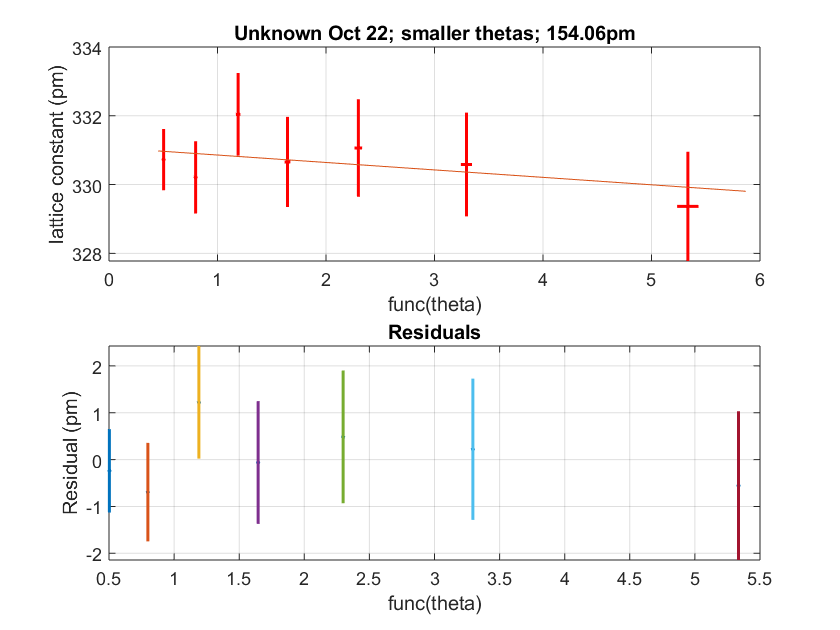

ans = 'CDF Value for graph:'

cdf = 0.9313

ans = 'Possible lattice spacings are'

poslat =   330.8000  330.6000  331.0000  330.4000  331.2000  330.2000  331.4000  330.0000  331.6000  329.8000


ans = 'Best lattice spacing is:'

ans = 331.0749

ans = 'With a standard deviation of:'

ans = 0.7026

ans = 'Could be one of the following elements: '

ans = 'Could be Niobium... (within 1.004944e+00 pm)'

ans = 'Could be Tantalum... (within 8.149437e-01 pm)'

ans = 'Could be Scandium... (within 1.749437e-01 pm)'

ans =    14.7000    0.0500
   16.0500    0.0500
   17.4000    0.0500
   18.6000    0.0500
   19.9000    0.0500
   21.3000    0.0500
   23.0000    0.0500


doplot = 1;
highres = 0;

lattice_analyzer2011(source, doplot, highres)

function  [rdata,ldata,rdata1,ldata1,rdatae,ldatae,inchol,outhol,wavel,litdplanes,dplanes,rchi2,sgness]...
        = lattice_analyzer2011(source,doplot,highres)

%{
        Written in October 2011
        by Marlon Nuske.
        
        License: Released under the MIT License; the full terms are this license
                are appended to the end of this file, and are also available
                at http://www.opensource.org/licenses/mit-license.php
        
!!! This program contains a vector with lattice constants of a couple of elements.
I have not written this data and already found two slight mistakes in it.
So be careful about the element that is predicted. This does not have any influence
on the fit and the lattice constant or any other output of the program. !!!     
   
To run the program you need to have the function fitchi2 in the same
directory. You can get it on http://www.mathworks.com/matlabcentral/fileexchange/9592-generalized-nonlinear-non-analytic-chi-square-fitting
        
        
This program is ment for X-Ray-Powder diffraction with known or unknown Samples.
It consists of three parts:
        If you give it the literature lattice constant of your sample it
        will choose the best wavelength and the best miller indices to get
        your measured values as close as possible to the literature lattice
        constant.
        
        If you set the literature lattice constant to 0and highres to 0, the program will
        try plenty of lattice constants and do a best fit. It will then
        give the same results as above for the calculated lattice constant.
        
        If this does not work out you can do a high resolution fit by
        setting highres to 1. Be aware that this might take a while. In the
        highresolution fit you will be given 10 different values that give
        a good fit and can than choose to throw some of them out. With the
        others the program will go on and give you the best fit of these.
        
@input parameters:
source is an Excel chart containing the relevant data in the order
number, right of the beam, error, left of the beam, error, incoming hole, outgoing, hole
wavelneth of xray, literature spacing of element (if you know otherwise put 0. Do
NOT leave it empty!). 
The next column must contain a title in the first row for plotting.
        
plot can be 1 or 0, put 1 if you want to have a Nelson Riley plot and fit,
else put 0.
        
If you want to do a high resolution search set highres to 1 otherwise 0.
        
An Example file is given in this folder, too, so you can see how you have to enter the data.
Make sure that the sheet containing the data is named Tabelle1 and that there is at least one
other empty sheet!!!
        
The Measurements have to be given in cm, all output values are given in pm.

An Excel sheet named "datana" will be added to the input file given in
source. So watch out, if you already have a sheet with that name it will be
overwritten. This Excel sheet contains all relevant data so there is no
need to use the output of this function. However if you want to do further
analysis with Matlab it might be useful.

%}
    
%color of the datapoints and errorbars
color='r';
colorf='k';
% List of elements in order of lattice constant
element_const = [2.8665;2.91000000000000;3.00500000000000;3.03000000000000;3.14700000000000;3.16500000000000;3.30070000000000;3.30260000000000;3.30900000000000;3.35900000000000;3.51000000000000;3.52400000000000;3.61500000000000;3.80300000000000;3.83900000000000;3.89000000000000;3.92400000000000;4.04950000000000;4.07820000000000;4.08530000000000;4.24400000000000;4.29000000000000;4.42900000000000;4.58100000000000;4.95000000000000;5.02800000000000;5.06000000000000;5.08420000000000;5.14800000000000;5.32800000000000;5.43090000000000;5.48470000000000;5.58840000000000;5.65750000000000;5.67000000000000;5.83180000000000;6.08490000000000;6.14100000000000;];
element_const = element_const*100;
% List of associated element names
element_names = {'Iron','Chromium','Mercury','Vanadium','Molybdenum','Tungsten','Niobium','Tantalum','Scandium','Polonium','Lithium','Nickel','Copper','Rhodium','Iridium','Palladium','Platinum','Aluminum','Gold','Silver','Helium','Sodium','Neon','Europium','Lead','Barium','Boron','Thorium','Radium','Potassium','Silicon','Ytterbium','Calcium','Germanium','Actinium','Tin','Strontium','Cesium';};


%Imports the document and saves the numbers in datad and the text in datat.
data=importdata(source);
datad=data.data.Tabelle1;
datat=data.textdata.Tabelle1;

%number is the amount of data sets.
%rdata is the data on the right side of beam including errors.
%ldata is data on the left side of beam including errors.
%rdata1 is the data on the right side of the beam.
%ldata1 is the data on the left side of the beam.
%rdatae are the errors of the data on the right side of the beam.
%ldatae are the errors of the data on the left side of the beam.
%inchol is the position of the incoming hole.
%outhol is the position of the outgoing hole.
%wavel are the different wavelenths of the used xray.

sized=size(datad);
number=sized(1);
inchol=datad(1,6);
inchole=datad(3,6);
outhol=datad(1,7);
outhole=datad(3,7);
for i=1:number
    rdata1(i)=datad(i,2);
    rdatae(i)=datad(i,3);
    ldata1(i)=datad(i,4);
    ldatae(i)=datad(i,5);
    rdata(i,1)=datad(i,2);
    rdata(i,2)=datad(i,3);
    ldata(i,1)=datad(i,4);
    ldata(i,2)=datad(i,5);
    if ~(isnan(datad(i,8)))
        wavel(i)=datad(i,8);
    end
end
i=1;
for j=1:number
    if isnan(rdata1(i))
        rdata1(i)=[];
        number=number-1;
    else
        i=i+1;
    end
end
i=1;
for j=1:number
    if isnan(rdatae(i))
        rdatae(i)=[];
    else
        i=i+1;
    end
end


%litdplanes is the literature spacing between two planes for the element.
litdplanes=datad(1,9);
%Define the function for the Nelson Riley Plot.
modelFun=@(a,x)a(1)*x+a(2);


%calculate the distances from the outgoing hole. Only take measurements
%between incoming and outgoing hole.
%dordata1 is the distances.
i=1;
j=0;
while (i+j)<=number
    if (~isnan(rdata1(i+j)))
    if (inchol < rdata1(i+j)) && (rdata1(i+j) < outhol)
        dordata1(i)=abs(outhol-rdata1(i+j));
        i=i+1;
    else
        sprintf('You tried to include data that is not on the right hand side of the beam!')
        j=j+1;
    end
    else
        j=j+1;
    end
end
if j~=0
    sprintf(strcat('You included  ',num2str(j),' sets of not valid data.'))
    number=number-j;
end

%Try different wavelengths and miller indices to find the corresponding
%ones.
if litdplanes~=0
    %If the lattice constant is known do this.
    [dplanes]=trywavelengths(dordata1,wavel,outhol,inchol,rdata1,litdplanes,number);
    %Now calculate the errors for these values.
    [dplanes,thetaer]=calerror(dplanes,dordata1,wavel,outhol,inchol,rdatae,inchole,outhole);
    sgness=sum((dplanes(:,3,1)-litdplanes).^2);
elseif highres==1
    gdplanes = 1:80;
    gdplanes = gdplanes*2.5
    gdplanes = gdplanes + 250;
    sgness(:,2) = 1:80;
    [~,a,~,~]=minimize_Nelson_Riley(dordata1,outhol,inchol,rdata1,...
        gdplanes,sgness,number,wavel,rdatae,inchole,outhole,10,modelFun);
    sizea=size(a);
    sizea=sizea(2);
    for i=1:sizea
        clear gdplanes;
        gdplanes = 1:10;
        for ii=1:10
            gdplanes(ii) = gdplanes(ii) + a(2,i) - 5;
        end
        clear sgness;
        sgness(:,2) = 1:10;
        [~,a2(:,i),~,~]=minimize_Nelson_Riley(dordata1,outhol,inchol,rdata1,...
        gdplanes,sgness,number,wavel,rdatae,inchole,outhole,1,modelFun);
    end
    sprintf(strcat('These are 10 possible lattice constants. Sometimes it \n',...
        'is very hard to find the right one, so you here have the possibility to \n',...
        'throw some of them out. The other ones will be further examined and the one \n',...
        'with the lowest rchi2 will be taken. Write a vector with a 0 for every data you \n',...
        'want to throw out and a 1 for all those you want to keep. Default is [1 1 1 1 ... 1]\n'))
    a2(2,:)
    [douse]=input('')
    if isempty(douse)
        douse(1:10)=1;
    end
    j=1;
    for i=1:10
        if douse(i)==0
            a2(:,j)=[];
        else
            j=j+1;
        end
    end
    clear a;
    a=a2(2,:);
    sizea=size(a);
    sizea=sizea(2);
    clear sgness;
    sgness(:,2)=1:sizea;
    [dplanes,a3,thetaer,rchi2]=minimize_Nelson_Riley(dordata1,outhol,inchol,rdata1,...
        a,sgness,number,wavel,rdatae,inchole,outhole,1,modelFun);
    clear a;
    a=a3;
else
    %As the lattice constant is not known, we calculate the theoretical
    %distances and try to minimize them against the experimental ones.
    gdplanes = 1:2000;
    gdplanes = gdplanes*0.2;
    gdplanes = gdplanes + 250;
    for j=1:1000
        [litdisr] = cal_dis_val(wavel,gdplanes(j),outhol,inchol);
        sized=size(litdisr);
        sized=sized(1);
        for i=1:number
            for k=1:sized
                if dordata1(i)<litdisr(k,1)
                    if k<sized
                        break
                    end
                end
            end
            if k==1
                k=2;
            end
            if abs(dordata1(i)-litdisr(k-1,1))<abs(dordata1(i)-litdisr(k,1))
                gness(j,i)=(abs(dordata1(i)-litdisr(k-1,1)))^2;
            else
                gness(j,i)=(abs(dordata1(i)-litdisr(k,1)))^2;
            end
        end
        sgness(j,1)=sum(gness(j,:));
    end
    sgness(:,2)=[1:1000];
    sgness=sortrows(sgness);
    sprintf('Possible lattice spacings are: ')
    %Take the best 10 values to further analyze which of them is the best.
    poslat=gdplanes(sgness(1:10,2))
    sgness2=sgness(1:10,:);
    sgness(:,2)=gdplanes(sgness(:,2));
    [dplanes,a,thetaer,rchi2]=minimize_Nelson_Riley(dordata1,outhol,inchol,rdata1,...
        gdplanes,sgness2,number,wavel,rdatae,inchole,outhole,1,modelFun);
end



       
%Write the data into the source excel file and add column names to the
%data.
sized=size(dplanes);
sized=sized(1);
name=cell(1,10);
name(1,1)={'plane distance in pm'};
name(1,2)={'error in pm'};
name(1,3)={'lattice constant in pm'};
name(1,4)={'error in pm'};
name(1,5)={'h'};
name(1,6)={'k'};
name(1,7)={'l'};
name(1,8)={'sqrt(h^2+k^2+l^2)'};
name(1,9)={'dist from left in cm'};
name(1,10)={'dist to outhol in cm'};
name(1,11)={'angle in rad'};
name(1,12)={'wavelength in pm'};
for m=1:(length(wavel)+1)
    xlswrite(source,dplanes(:,:,m),'datana',strcat('A',num2str((m-1)*(sized+3)+2)));
    xlswrite(source,name,'datana',strcat('A',num2str((m-1)*(sized+3)+1)));
end




%Plots data.
if doplot==1
    %Prepare data for Nelson Riley plot.
    sizedplanes=size(dplanes);
    sizedplanes=sizedplanes(1);
    for i=1:sizedplanes
        win=dplanes(i,11);
        nerix(i)=(cos(win))^2*(1/win+1/sin(win));
        %nerix1(i)=(cos(win))^2/win;
        %nerix2(i)=(cos(win))^2/sin(win);
        neriy(i)=dplanes(i,3,1);
    end
    
    
    hold on;
    subplot(2,1,1)
    plot(nerix,neriy,'.','Color',color);
    %plot(nerix1,neriy,'.','Color','k');
    %plot(nerix2,neriy,'.','Color','b');
    xlabel('func(theta)','FontSize',8);
    ylabel('lattice constant (pm)','FontSize',8);
    title(datat(1,10),'FontSize',8);
    grid on;
    xdata1=nerix;
    ydatae=transpose(dplanes(:,4,1));
    ydata1=neriy;
    xdatae=transpose(thetaer(:,1));
    % Plot error bars as specified
    line([xdata1-xdatae;xdata1+xdatae],[ydata1;ydata1],'LineStyle','-','Color',color,'LineWidth',1.5);
    line([xdata1;xdata1],[ydata1-ydatae;ydata1+ydatae],'LineStyle','-','Color',color,'LineWidth',1.5);

    hold off;
    
    %Fit a function to the plot and plot function
    [a,errora,rchi2,cdf]=fitdata(xdata1,ydata1,xdatae,ydatae,modelFun,[1 400],1);
    
    sprintf('CDF Value for graph:')%display the cdf value under the graph
    cdf
    
    %Save the calculated lattice constant into the Excel sheet together
    %with error.
    xlswrite(source,{'calculated lattice constant', 'error'},'datana','N1');
    xlswrite(source,[a(2) errora(2)],'datana','N2');
    xlswrite(source,{'rchi2'},'datana','N3');
    xlswrite(source,rchi2,'datana','N4');
    xlswrite(source,{'CDF'},'datana','N5');
    xlswrite(source,cdf,'datana','N6');
end

if (litdplanes==0 && highres ~= 1)
    sprintf('Possible lattice spacings are')
    poslat
end
sprintf('Best lattice spacing is:')
a(2)
sprintf('With a standard deviation of:')
errora(2)


sprintf('Could be one of the following elements: ')
for j=1:length(element_const)
    e = abs(element_const(j)-a(2));
    if(e < errora(2)*2)
        sprintf('Could be %s... (within %d pm)',element_names{j},e)
    end
end

    end

function [dplanes,a,thetaer,rchi2]=minimize_Nelson_Riley(dordata1,outhol,inchol,rdata1,...
    gdplanes,sgness,number,wavel,rdatae,inchole,outhole,numout,modelFun)
sized=size(sgness);
sized=sized(1);
for i=1:sized
    [dplanes(:,:,:,i)]=trywavelengths(dordata1,wavel,outhol,inchol,rdata1,gdplanes(sgness(i,2)),number);
    %Now calculate the errors for these values.
    [dplanes(:,:,:,i),thetaer(:,:,i)]=calerror(dplanes(:,:,:,i),dordata1,wavel,outhol,inchol,rdatae,inchole,outhole);
    %Now fit data with a Nelson Riley plot. Find data with lowest
    %reduced chi2.

    %Prepare data for Nelson Riley plot.
        sizedplanes=size(dplanes);
        sizedplanes=sizedplanes(1);
        for j=1:sizedplanes
            win=dplanes(j,11);
            nerix(j)=(cos(win))^2*(1/win+1/sin(win));
            neriy(j)=dplanes(j,3,1,i);
        end
    [a(:,i),~,rchi2(i), cdfLocal1]=fitdata(nerix,neriy,transpose(thetaer(:,1,i)),transpose(dplanes(:,4,1,i)),modelFun,[1 400],0);
end
[rchi2,indexbest]=sort(rchi2);
rchi2(numout+1:length(rchi2))=[];
indexbest(numout+1:length(indexbest))=[];
a=a(:,indexbest);
dplanes=dplanes(:,:,:,indexbest);
thetaer=thetaer(:,:,i);
end

function [a,errora,rchi2,cdf]=fitdata(xdata1,ydata1,xdatae,ydatae,modelFun,guess,doplot)
%Assure which data shall be fitted. Not used anymore.
xdataf=xdata1;
ydataf=ydata1;
xdatafe=xdatae;
ydatafe=ydatae;


%Fits data.
[params,dParams,gof,stddev] = fitChiSquare(xdataf,ydataf,modelFun,guess,xdatafe,ydatafe);
a=params;

%Standardabweichung for a als Vektor.
for i=1:length(a)
    errora(i)=dParams(1,i).d;
end

%chi-squared ausgeben.
chi2=gof.chi2;
dof=gof.dof;
rchi2=chi2/dof;
cdf = gof.probChi2;

if doplot==1
    %plotFun ist nur noch von x abhängig nicht mehr von a
    plotFun=@(x)modelFun(a,x);

    if doplot==1
        hold on;
        fplot(plotFun,[(min(xdata1)-0.1*mean(min(xdata1))) (max(xdata1)+0.1*mean(max(xdata1)))]);
        
        %plot a residuals plot
        subplot(2,1,2)
        plot(xdataf,(ydataf-plotFun(xdataf)),'.');
        xlabel('func(theta)','FontSize',8);
        ylabel('Residual (pm)','FontSize',8);
        title("Residuals",'FontSize',8);
        grid on;
        %plot error bars
        line([xdataf;xdataf],[ydataf-plotFun(xdataf)-ydatafe;ydataf-plotFun(xdataf)+ydatafe],'LineStyle','-','LineWidth',1.5);

        
        hold off;
    end
end

end
    
function [dplanes]=trywavelengths(dordata1,wavel,outhol,inchol,rdata1,litdplanes,number)
%now calculate the spacing between two planes, knowing the correct spacing
%and using the n that has the best result.

%dplanes contains in the colums:
%   1.  distance between planes
%   2.  error for the distance between planes
%   3.  calculated lattice constant for the atom
%   4.  error for the calc lattice constant
%   5.-7. miller indices for the calculated spacing
%   8.  squareroot of squares of miller indices
%   9.  measured distance on the film from left end
%   10.  measured distance on the film from outhole
%   11.  angle between outhole and measurement
%   12.  used wavelength


j=1;
%Get matrix with miller indices.
[milind]=miller(10);
for i=1:number
    if dordata1(i)~=0
        for m=2:(length(wavel)+1)
            %Calculate dplanes for all the different wavelenths. Third dimesion
            %is used to put the different wavelenths in.
            dplanes(j,1,m)=wavel(m-1)/(2*sin(pi*dordata1(i)/(2*(outhol-inchol))));
            dplanes(j,9,m)=rdata1(i);
            dplanes(j,11,m)=pi*dordata1(i)/(2*(outhol-inchol));
            [dplanes(j,:,m)]=try_miller(dplanes(j,:,m),milind,litdplanes);
            dplanes(j,12,m)=wavel(m-1);
            dplanes(j,10,m)=dordata1(i);
        end
        %Now compare all the different wavelenths and find the best fit.
        sized=size(dplanes);
        sized=sized(3);
        [~,index]=min(abs(dplanes(j,3,2:sized)-litdplanes));
        index=index+1;
        dplanes(j,:,1)=dplanes(j,:,index);
        dplanes(j,12,1)=wavel(index-1);
        %gness(j)=(abs(dplanes(j,3,1)-litdplanes))^2;
        j=j+1;
    end
end
%gness=sum(gness);
end
    
function [dplanes]=try_miller(dplanes,milind,litdplanes)
%Tries the different miller indices for the input and results the best fit.
dplanes(3)=dplanes(1);
dplanes(5:8)=milind(1:4);
n=2;
    while n~=0
        if abs(dplanes(3)*milind(n,4)-litdplanes) <= abs(dplanes(3)*milind(n-1,4)-litdplanes)
            n=n+1;
        else
            n=n-1;
            dplanes(3)= dplanes(3)*milind(n,4);
            dplanes(5:8)=milind(n,1:4);
            n=0;
        end
    end
end

function [litdisr] = cal_dis_val(wavel,litdist,outhol,inchol)
%Takes the literature value for the lattice spacing and calculates the
%distances to the outgoing hole, that would be measured.

%1. column contains the value, second to fourth the corresponding miller
%indices and 5th the wavelenth.

[mil]=miller(10);
sizemil=size(mil);
sizemil=sizemil(1);
for i=1:sizemil
    for j=1:length(wavel)
        litdisr(i+(j-1)*sizemil,1)= 2*asin(wavel(j)/2/(litdist/mil(i,4)))/pi*(outhol-inchol);
        litdisr(i+(j-1)*sizemil,2:4)=mil(i,1:3);
        litdisr(i+(j-1)*sizemil,5)=wavel(j);
    end
end
litdisr=sortrows(litdisr,1);
sizelit=size(litdisr);
sizelit=sizelit(1);
for i=1:sizelit
    if ~isreal(litdisr(i,1))
        litdisr(i:sizelit,:)=[];
        break
    end
end
end

function [dplanes,thetaer]=calerror(dplanes,dordata1,~,outhol,inchol,rdatae,inchole,outhole)
sized=size(dplanes);
for i=1:sized(1)
    for j=1:sized(3)
        while dplanes(i,10,j)~=dordata1(i)
            dordata1(i)=[];
            rdatae(i)=[];
        end
        win=dplanes(i,11,j);
        rdatae(i)=sqrt(rdatae(i)^2+outhole^2);
        winer=sqrt((pi/(outhol-inchol)/2*rdatae(i))^2+(pi*dplanes(i,10,j)/2/(outhol-inchol)^2*outhole)^2+(pi*dplanes(i,10,j) ... 
            /2/(outhol-inchol)^2*inchole)^2);
        thetaer(i,j)=(sin(win)*2*cos(win)*(1/win+1/sin(win))+(cos(win))^2*(1/win^2+cos(win)/(sin(win))^2))*winer;
        errord=dplanes(i,12,j)/2/sin(win)*cos(win)*pi/(outhol-inchol)/2*rdatae(i);
        errorin=dplanes(i,12,j)/2/sin(win)*cos(win)*pi*dplanes(i,10,j)/2/(outhol-inchol)^2*outhole;
        errorout=dplanes(i,12,j)/2/sin(win)*cos(win)*pi*dplanes(i,10,j)/2/(outhol-inchol)^2*inchole;
        dplanes(i,2,j)=sqrt(errord^2+errorin^2+errorout^2);
        dplanes(i,4,j)=dplanes(i,2,j)*dplanes(i,8,j);
    end
end
end

function [A]=miller(n)
%Creates a matrix A of the miller indices for the planes without the
%multiples of the planes and sorted by the squareroot of the squares. n is
%the maximum number that this squareroot can take.

%miller indices
h=1;
k=0;
l=0;

i=1;
while h<=n
    while k<=h
        while l<=k
            %if (gcd(h,k)<=1 && gcd(h,l)<=1 && gcd(k,l)<=1)
                A(i,:)=[h k l sqrt(h^2+k^2+l^2)];
                i=i+1;
            %end
            l=l+1;
        end
        k=k+1;
        l=0;
    end
    h=h+1;
    k=0;
end

%Sort Matrix and make sure that the squareroot is not bigger than n.

A=sortrows(A,4);
sizeA=size(A);
sizeA1=sizeA(1);
for i=1:sizeA1
    if A(i,4)>n
        A(i:sizeA1,:)=[];
        break
    end
end

%{
Full text of MIT License:

    Permission is hereby granted, free of charge, to any person obtaining a copy
of this software and associated documentation files (the "Software"), to deal
in the Software without restriction, including without limitation the rights
to use, copy, modify, merge, publish, distribute, sublicense, and/or sell
copies of the Software, and to permit persons to whom the Software is
furnished to do so, subject to the following conditions:

The above copyright notice and this permission notice shall be included in
all copies or substantial portions of the Software.

THE SOFTWARE IS PROVIDED "AS IS", WITHOUT WARRANTY OF ANY KIND, EXPRESS OR
IMPLIED, INCLUDING BUT NOT LIMITED TO THE WARRANTIES OF MERCHANTABILITY,
FITNESS FOR A PARTICULAR PURPOSE AND NONINFRINGEMENT. IN NO EVENT SHALL THE
AUTHORS OR COPYRIGHT HOLDERS BE LIABLE FOR ANY CLAIM, DAMAGES OR OTHER
LIABILITY, WHETHER IN AN ACTION OF CONTRACT, TORT OR OTHERWISE, ARISING FROM,
OUT OF OR IN CONNECTION WITH THE SOFTWARE OR THE USE OR OTHER DEALINGS IN
THE SOFTWARE.
%}

end